# Lab 2

**Physics 434**

**Francesca Bennett**

Collaborators: Taylor Prewitt, Natalie Shen

clear all; close all;


## **Problem 1**

**Part 1.A**

%x axis
x = [0:24];
%avgBackground 
X = 7;

poisson = makedist("Poisson",'lambda',X);
%subplot(3,2,1)
Pdist=poisspdf(x,X)

Pdist =     0.0009    0.0064    0.0223    0.0521    0.0912    0.1277    0.1490    0.1490    0.1304    0.1014    0.0710    0.0452    0.0263    0.0142    0.0071    0.0033    0.0014    0.0006    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


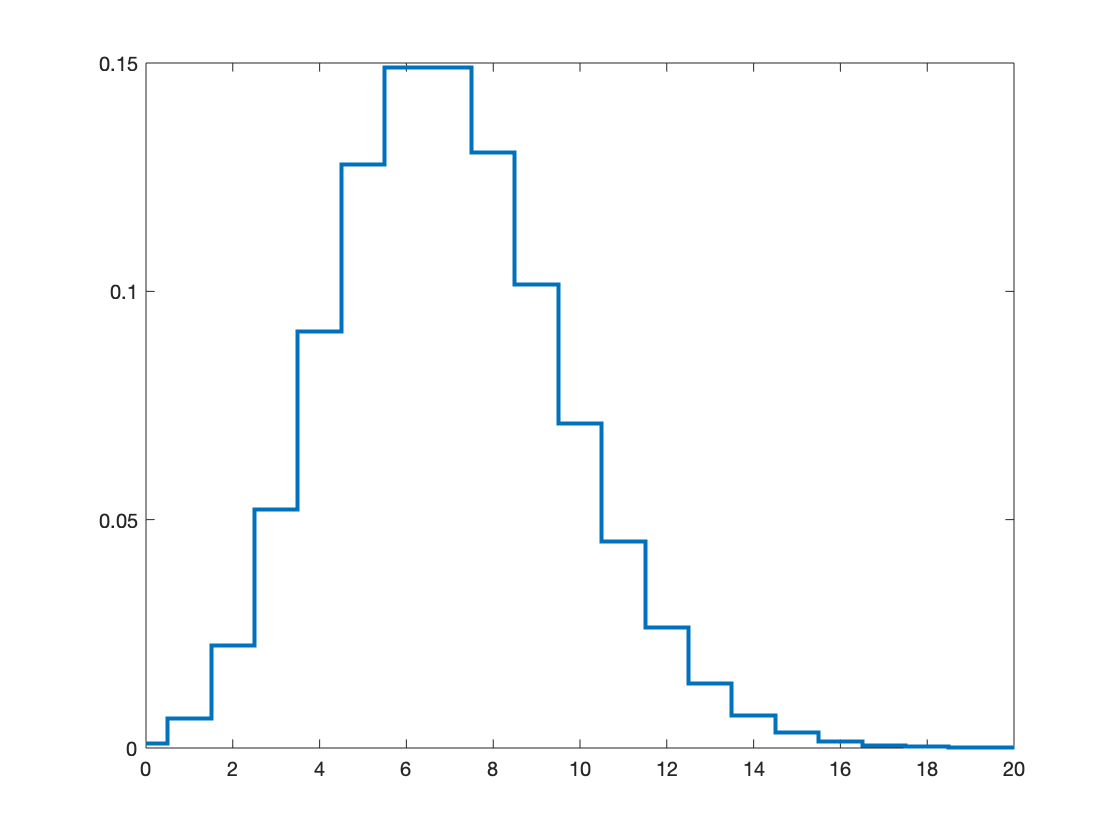



stairs(x-0.5,pdf(poisson,x),"Linewidth",2);
%set(gca,'YScale','log')
xlim([0,20])

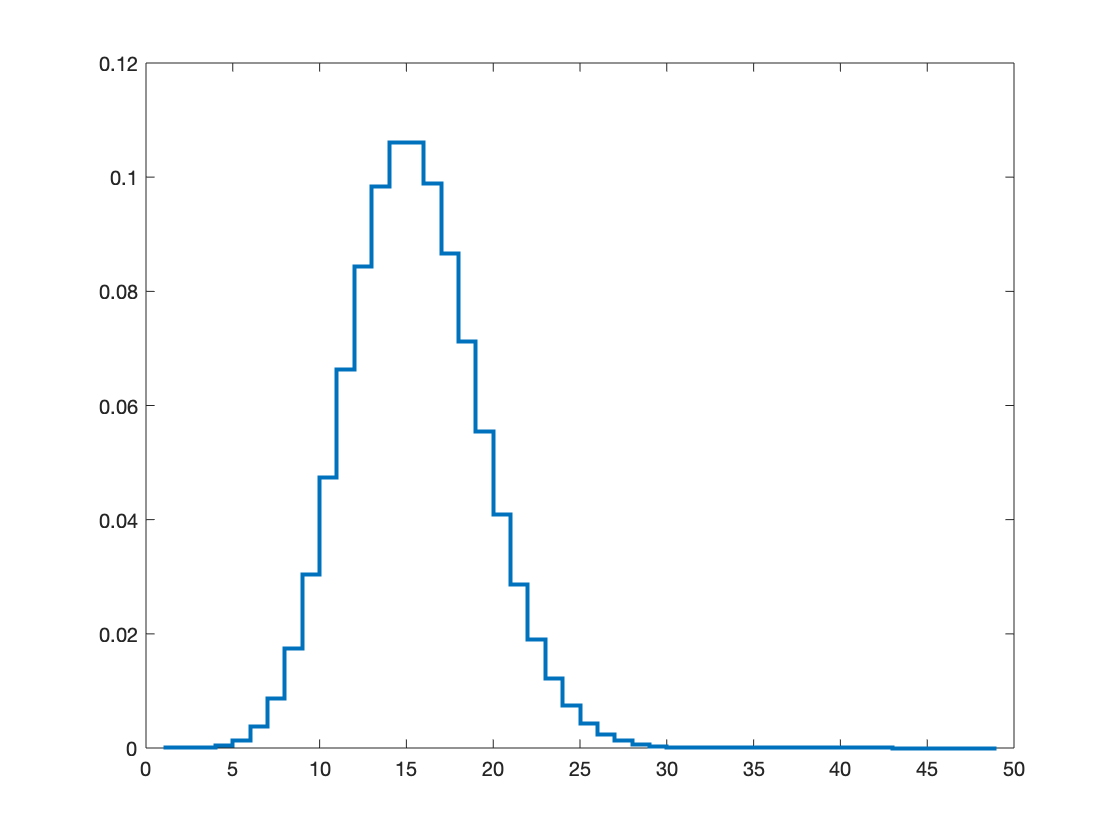


%The convolution sums the background change for each day
%subplot(3,2,2)
c1=conv(Pdist,Pdist);

stairs(c1,"Linewidth",2)

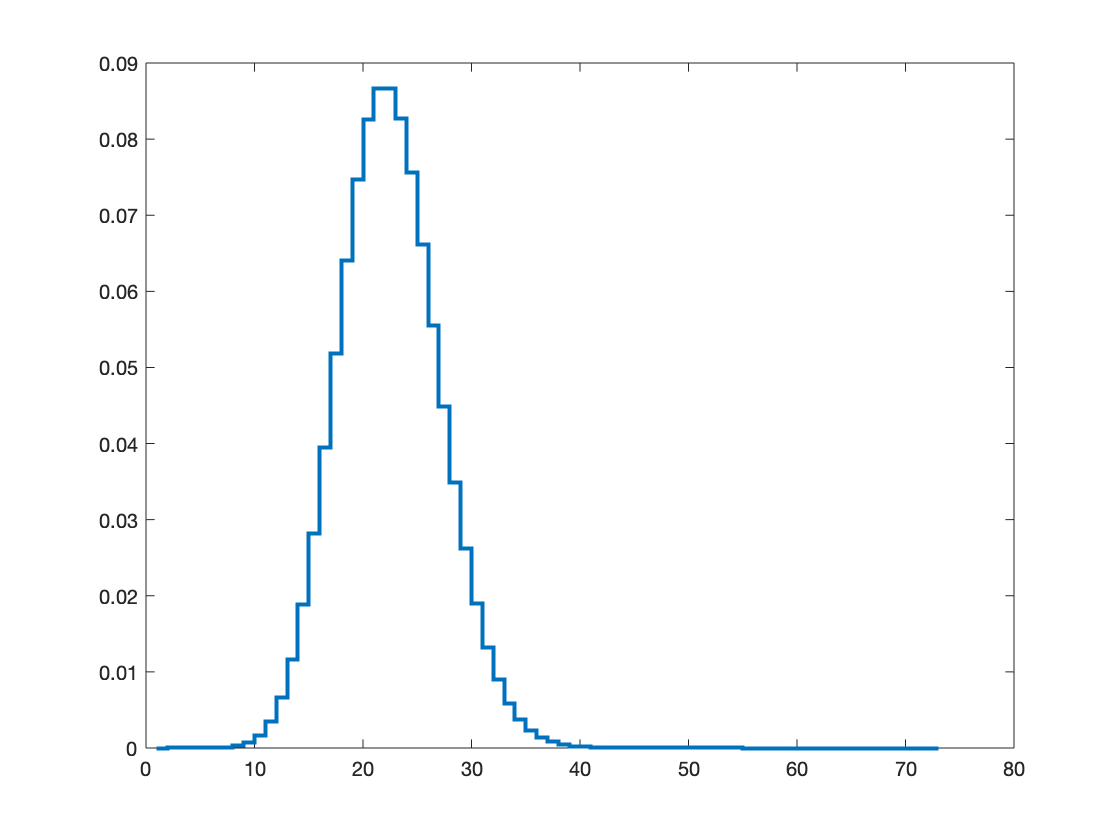


%subplot(3,2,3)
c2=conv(Pdist,c1);
stairs(c2,"Linewidth",2)

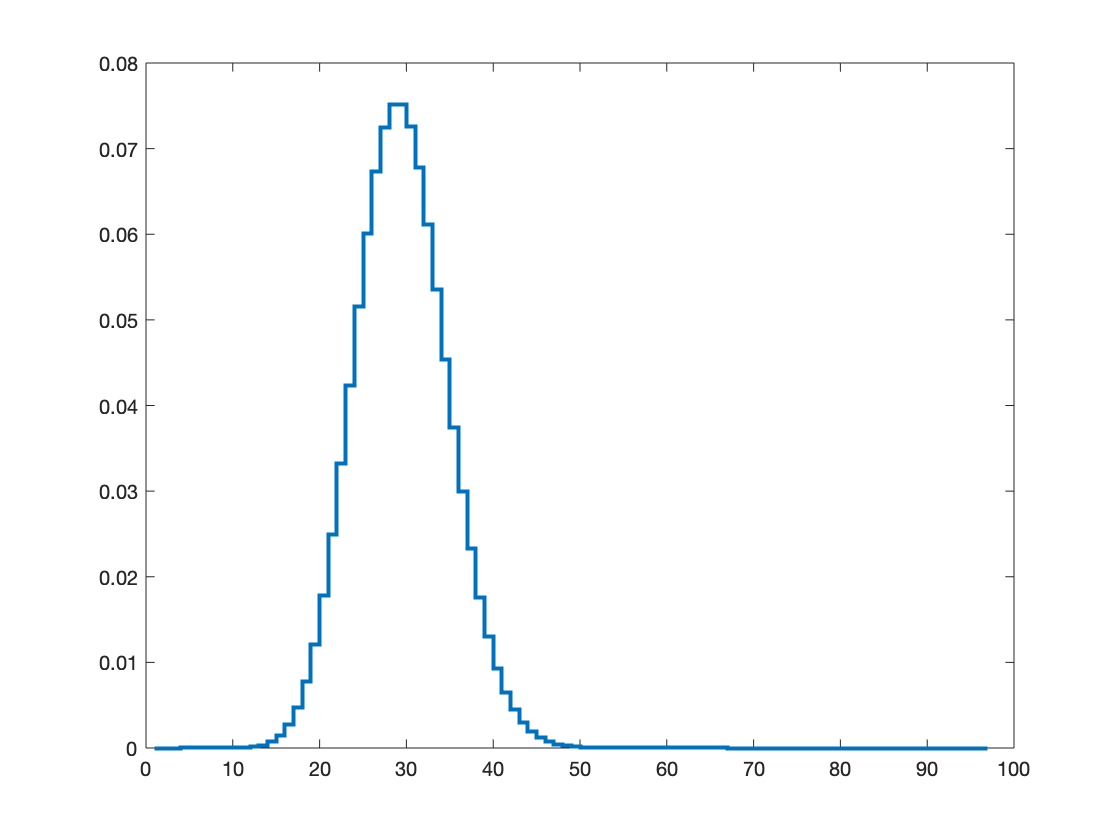


%subplot(3,2,4)
c3=conv(Pdist,c2);
stairs(c3,"Linewidth",2)

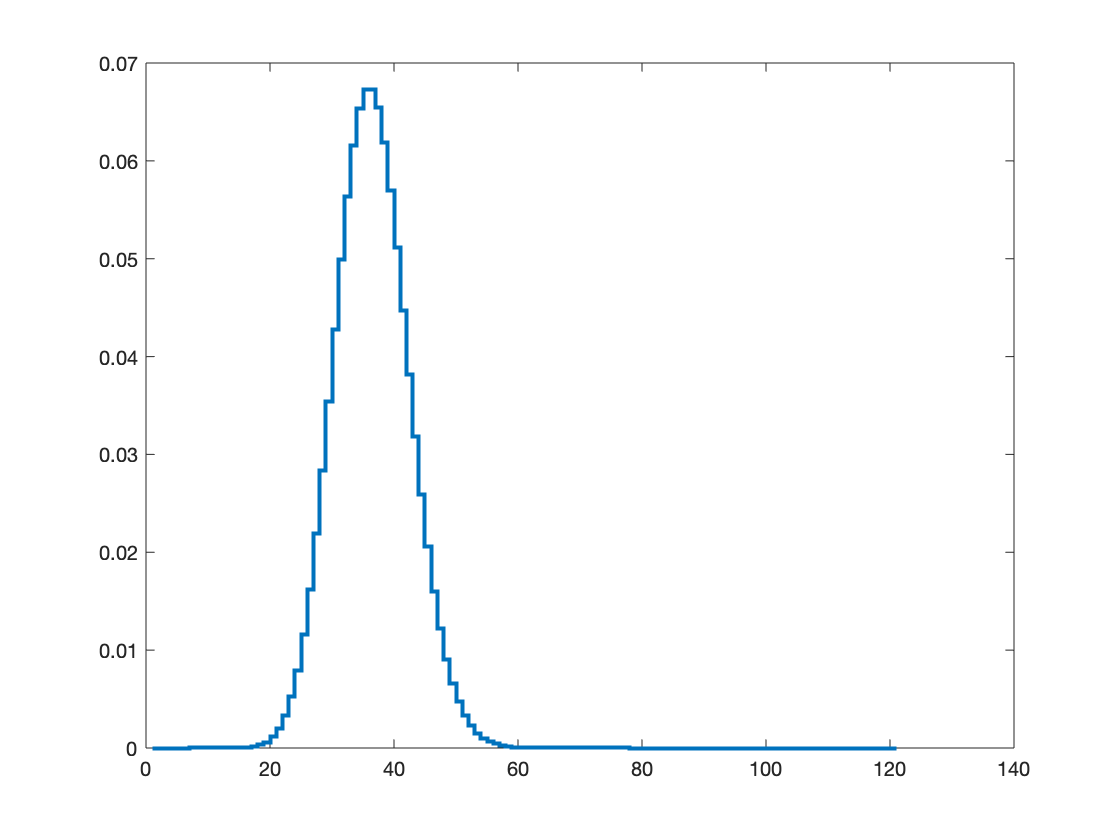


%subplot(3,2,5)
c4=conv(Pdist,c3);
stairs(c4,"Linewidth",2)

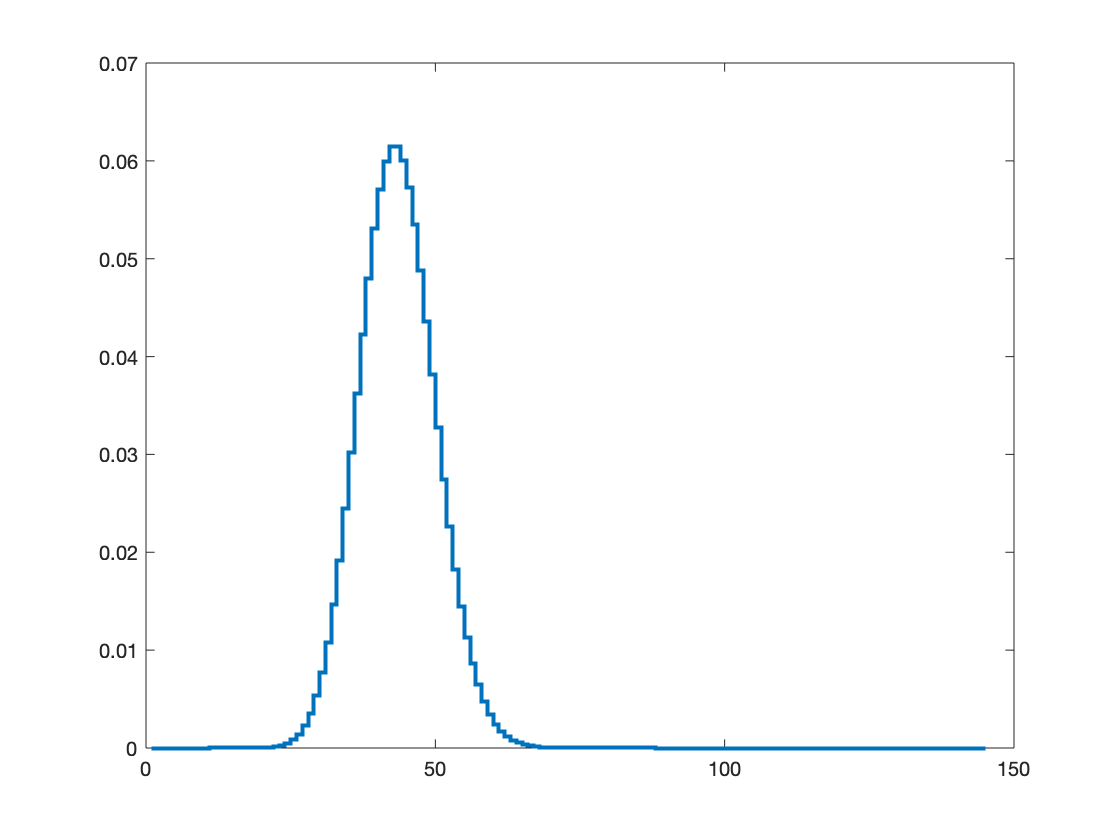


%subplot(3,2,6)
c5=conv(Pdist,c4);

stairs(c5,"Linewidth",2)

As further convolutions are taken, the distribution becomes more Guassian, and hence symmetrical.

**Part 1.B**

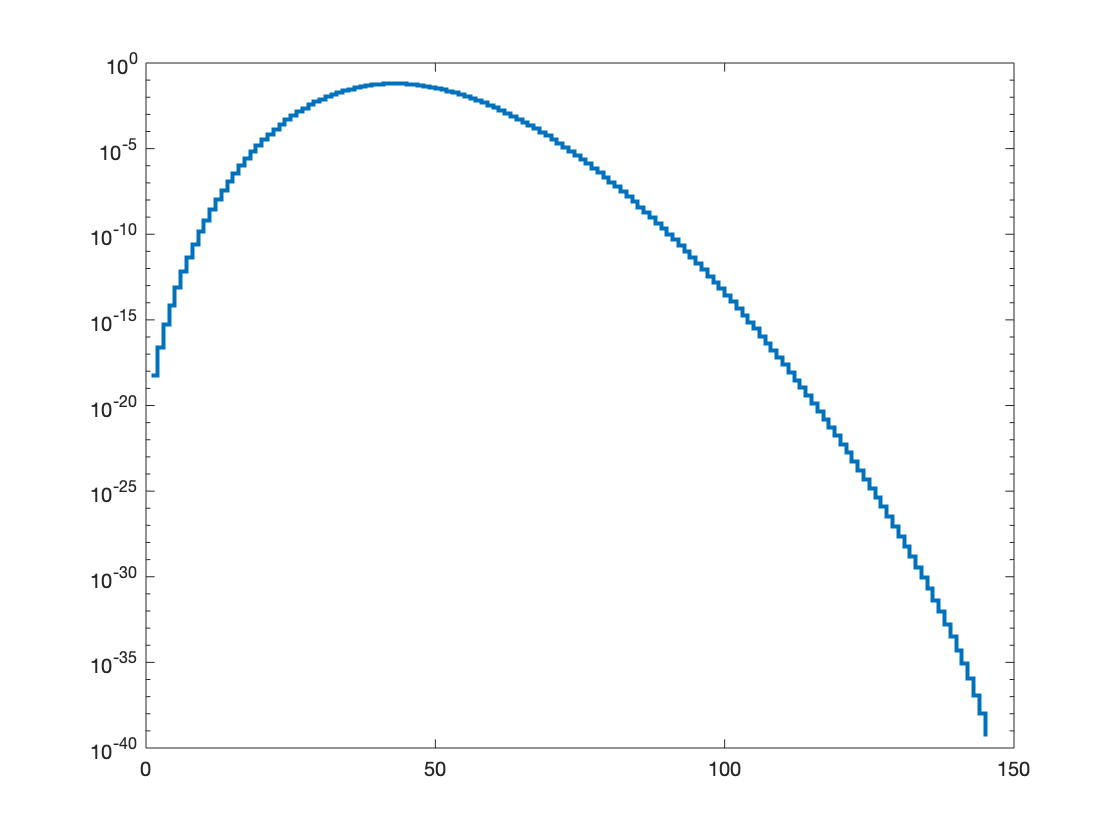

stairs(c5,"Linewidth",2)
title("Final Convolution, Logrithmic Scale")
xlabel("counts")
ylabel("probability")
set(gca,'YScale','log')

**Part 1. C**

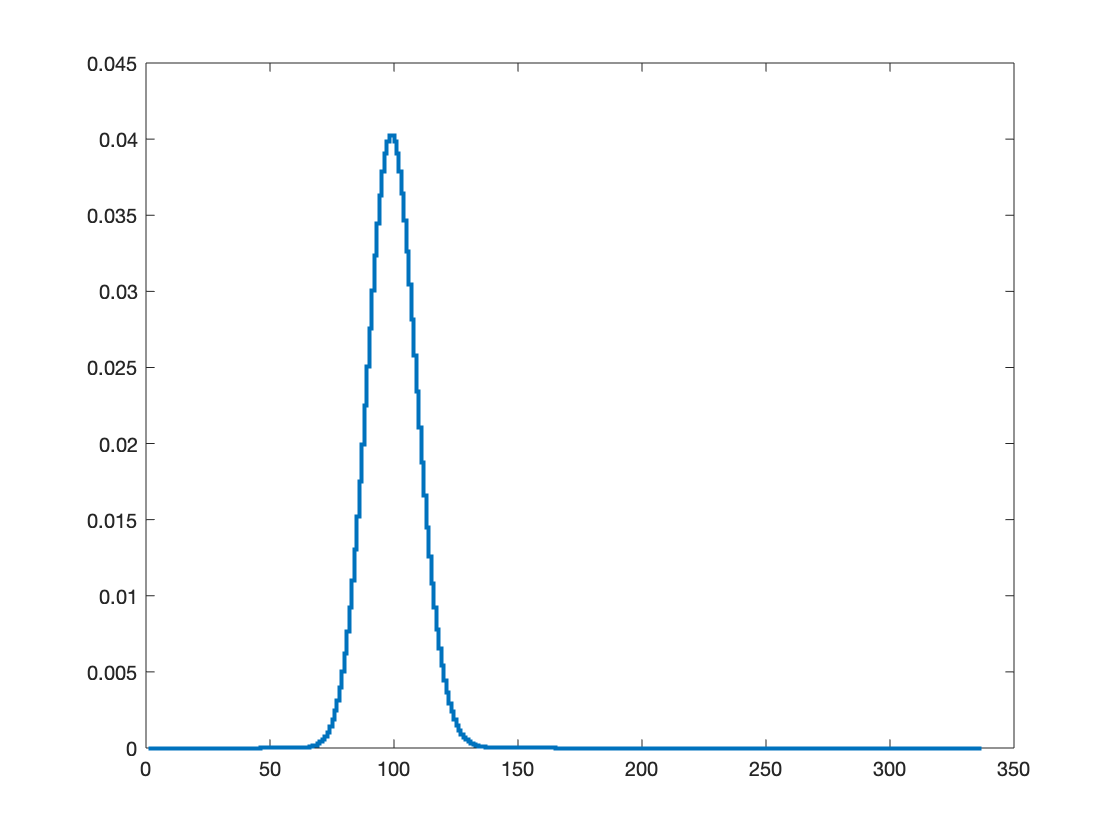

%more days being convoluted
c6=conv(Pdist,c5);
c7=conv(Pdist,c6);
c8=conv(Pdist,c7);
c9=conv(Pdist,c8);
c10=conv(Pdist,c9);
c11=conv(Pdist,c10);
c12=conv(Pdist,c11);
c13=conv(Pdist,c12);

stairs(c13,"Linewidth",2);

**Part 1.D**

Integral: lambda value should X: "how likely is it given my background that I will see this measurement"


N=10;
Y=10;
number=100;

%X is lambda for one day
%not sure if Y is N*Y or just Y, it should be lambda
Pr1 = poisscdf((N*Y),70,'upper')

Pr1 = 2.9259e-04


%det = icdf(poisson, 1-Pr1/Y);
%
abs(norminv(Pr1,0,1))

ans = 3.4384

%(1-cdf(poisson,15))*Y




## Problem 3

**Version 1**

**Part 3.A**

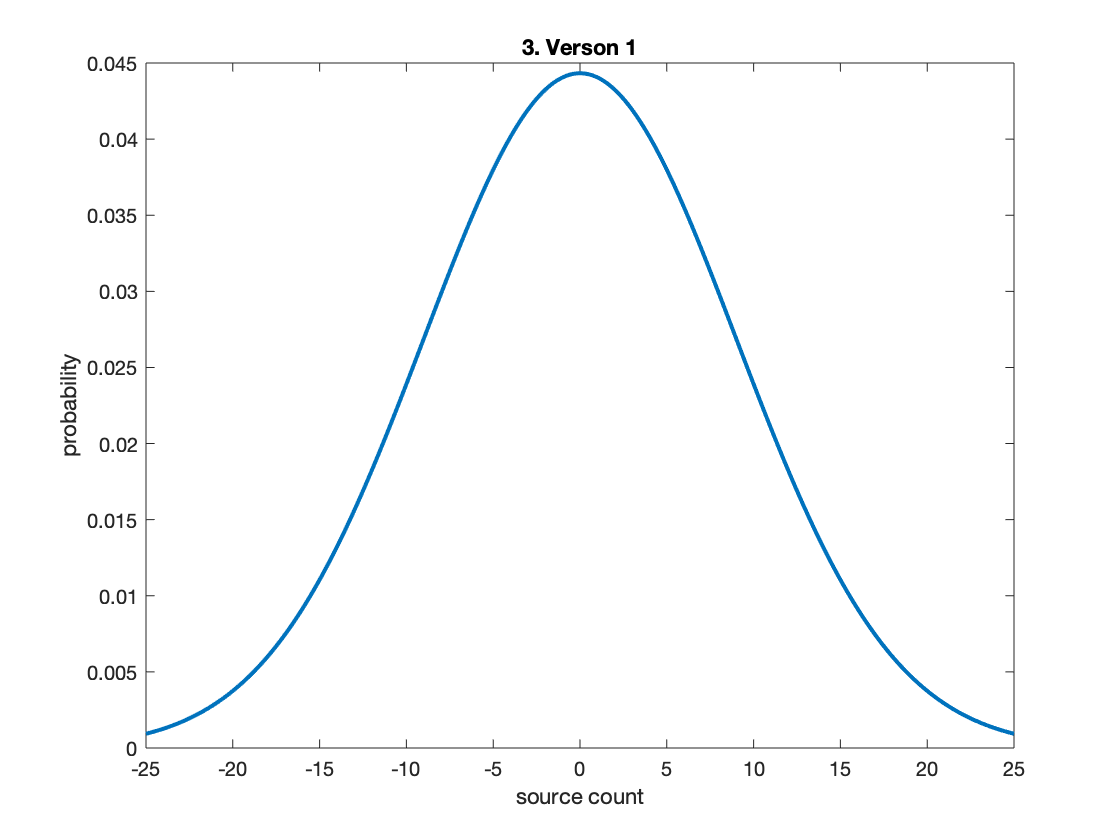

mu=0;
sigma1=9;
Dist1 = makedist('Normal', 'mu',mu,'sigma',sigma1);
S1=linspace(-25,25,1000);

plot(S1,pdf(Dist1,S1),"Linewidth",2);
title("3. Verson 1");
xlabel("source count");
ylabel("probability");

%??? not sure why other plots from part 1 appear

sigmaV1=abs(norminv(1-normcdf(19,0,9)))

sigmaV1 = 2.1111

**Version 2**

**Part 3.B**

What is the probability distribution of the background if we sum the signal over 10,000 pixels?

**Part 3.C**

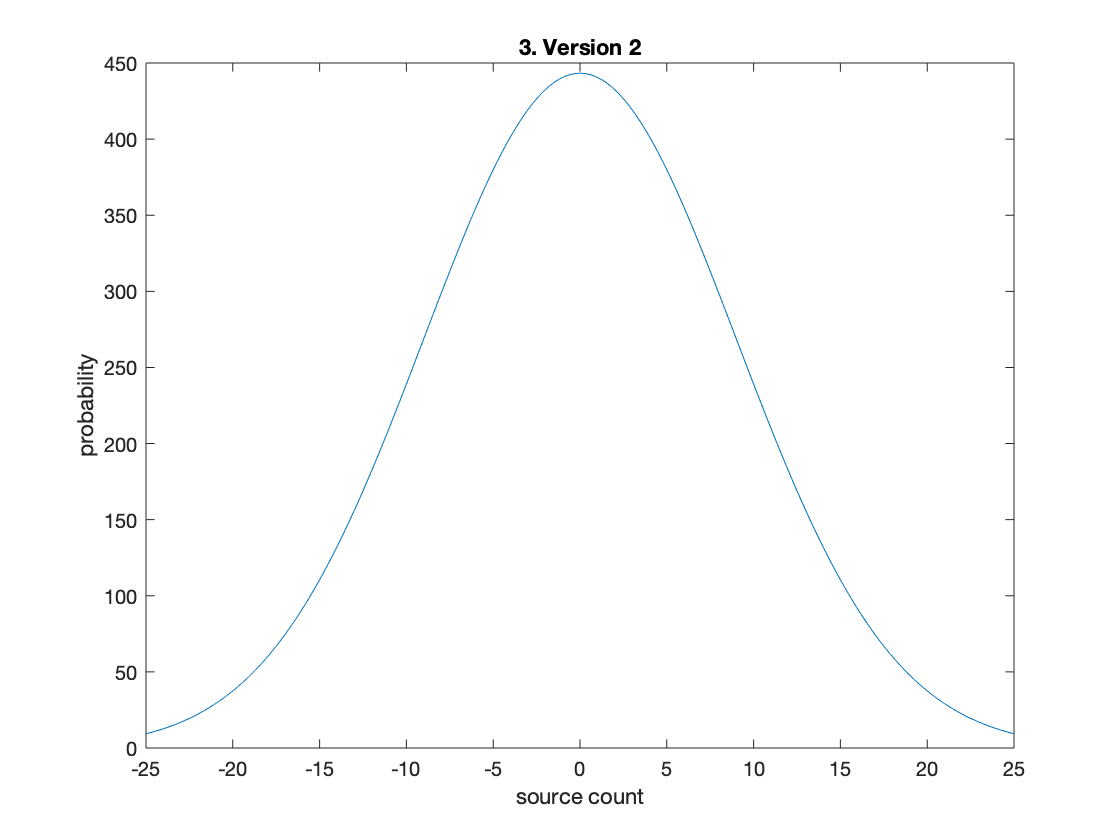

pixels=10000;

plot(S1,pdf("normal",S1,0,9)*pixels)
title("3. Version 2")
xlabel("source count")
ylabel("probability")


value=19;
V22=(1-cdf("Normal",value,0,5))*pixels;

## Problem 4

**Part 4.A**


prob5s = 1/3.5e6;
valA = icdf("normal", 1- prob5s,0,5)

valA = 25.0032

**Part 4.B**

valB = icdf("normal", (1- prob5s)/pixels,0,5)

valB = -18.5951

**Part 4.C**

valC=abs(valA-valB)

valC = 43.5982